clc;
clear;

## 向前行走

% 设定步行参数
g = 9.81;
z = 0.5;
b = sqrt(z/g);

% 暂定参数
dt = 0.01;
t_transfer = 0.75; %0.1;
t_ss = 1.0; %0.4; 
t_ds = 0.25; %0.05; 
alpha = 0.5;
t_ds_ini = alpha*t_ds;
t_ds_end = (1-alpha)*t_ds;

% 设定一段指数收敛时间，使得在仿真结束时CoM已经收敛至DCM
percentage_settle = 0.99;
t_settle = -b*log(1.0 - percentage_settle);  

% 初始化双脚位置
rfoot_y = -0.1025;
lfoot_y = 0.1025;
midfeet_y = (lfoot_y +rfoot_y)/2.0;

% 初始化DCM状态
xi_init_state = [0.0; midfeet_y; z];
xi_vel_init_state = [0.0; 0.0; 0.0];

% 初始化CoM状态
com_init_state = [0.0; midfeet_y; z];
com_vel_init_state = [0.0; 0.0; 0.0];

% 初始化DCM容器
r_vrp = zeros(3,10);
n = size(r_vrp, 2);
t_step = zeros(1, n);
xi_ini = zeros(3, n);
xi_eos = zeros(3, n);
xi_hat_ini = zeros(3, n);
xi_hat_eos = zeros(3, n);

% 设定VRP 
r_vrp(:,1) = [0, midfeet_y, z];
r_vrp(:,2) = [0, lfoot_y, z];
r_vrp(:,3) = [0.2, rfoot_y,  z];
r_vrp(:,4) = [0.4, lfoot_y,  z];
r_vrp(:,5) = [0.6, rfoot_y, z];
r_vrp(:,6) = [0.8, lfoot_y, z];
r_vrp(:,7) = [1.0, rfoot_y, z];
r_vrp(:,8) = [1.2, lfoot_y,  z];
r_vrp(:,9) = [1.4, rfoot_y,  z];
r_vrp(:,10) = [1.4, midfeet_y, z];

% 设定每一步的时间(这里怎么设置比较合理？？) 
t_step(:,1) = t_transfer + t_ds;
t_step(:,2) = t_ss + t_ds;
t_step(:,3) = t_ss + t_ds;
t_step(:,4) = t_ss + t_ds;
t_step(:,5) = t_ss + t_ds;
t_step(:,6) = t_ss + t_ds;
t_step(:,7) = t_ss + t_ds;
t_step(:,8) = t_ss + t_ds;
t_step(:,9) = t_ss + t_ds;
t_step(:,10) = (1-alpha)*t_ds;  
=
% 用于计算插值多项式的容器
xi_ini_DS = zeros(3, n);
xi_ini_vel_DS = zeros(3, n);
xi_end_DS = zeros(3, n);
xi_end_vel_DS = zeros(3, n);
xi_hat_ini_DS = zeros(3, n);
xi_hat_ini_vel_DS = zeros(3, n);
xi_hat_end_DS = zeros(3, n);
xi_hat_end_vel_DS = zeros(3, n);
t_ds_vec = ones(1,n)*t_ds;
t_ds_vec(1) = t_transfer + t_ds + (1-alpha)*t_ds;
P_mats = zeros(4,3,n);
P_hat_mats = zeros(4,3,n);

文章中提到 $\xi_{d,eos,i-1}=\xi_{d,ini,i}=\mathbf{r}_{vrp,d,i}+e^{-\frac{t_{step}}{b}}(\xi_{d,eos,i}-\mathbf{r}_{vrp,d,i})$

% 递归求解DCM的边界条件
xi_eos(:,end) = r_vrp(:,end);
for(i = 1:n)
    i = n-i+1;
    xi_ini(:,i) = r_vrp(:,i) + exp(-(1/b)*t_step(i)) * (xi_eos(:,i) - r_vrp(:,i));
    if (i > 1)
        xi_eos(:,i-1) = xi_ini(:,i);
    end
end

% 递归求解CCM的边界条件
xi_hat_ini(:,1) = r_vrp(:,1);
for(i = 1:n)
    xi_hat_eos(:,i) = r_vrp(:,i) + exp(-(1/b)*t_step(i)) * (xi_hat_ini(:,i) - r_vrp(:,i));
    if (i < size(xi_hat_ini, 2))
        xi_hat_ini(:,i+1) = xi_hat_eos(:,i);
    end
end

% 设定双足支撑的边界条件
% 开始双足支撑的条件
xi_ini_DS(:,1) = xi_init_state;
xi_ini_vel_DS(:,1) = xi_vel_init_state;
xi_hat_ini_DS(:,1) = xi_hat_ini(:,1);
xi_hat_ini_vel_DS(:,1) = xi_vel_init_state;
for(i = 2:n)
    xi_ini_DS(:,i) = r_vrp(:,i-1) + exp((-1/b)*t_ds_ini)*(xi_ini(:,i) - r_vrp(:,i-1));        
    xi_ini_vel_DS(:,i) = (1/b)*exp((-1/b)*t_ds_ini)*(xi_ini(:,i) - r_vrp(:,i-1));        
    xi_hat_ini_DS(:,i) = r_vrp(:,i-1) + exp((1/b)*t_ds_ini) * (xi_hat_ini(:,i) - r_vrp(:,i-1));
    xi_hat_ini_vel_DS(:,i) = -(1/b)*exp((1/b)*t_ds_ini) * (xi_hat_ini(:,i) - r_vrp(:,i-1));
end

% 结束双足支撑的条件
for(i = 1:n)
    xi_end_DS(:,i) = r_vrp(:,i) + exp((1/b)*t_ds_end)*(xi_ini(:,i) - r_vrp(:,i));
    xi_end_vel_DS(:,i) = (1/b)*exp((1/b)*t_ds_end)*(xi_ini(:,i) - r_vrp(:,i));
    xi_hat_end_DS(:,i) = r_vrp(:,i) + exp(-(1/b)*t_ds_end) * (xi_hat_ini(:,i) - r_vrp(:,i));
    xi_hat_end_vel_DS(:,i) = -(1/b)*exp(-(1/b)*t_ds_end) * (xi_hat_ini(:,i) - r_vrp(:,i));
end
xi_end_DS(:,1) = xi_end_DS(:,2);
xi_end_vel_DS(:,1) = xi_end_vel_DS(:,2);
xi_hat_end_DS(:,1) = xi_hat_end_DS(:,2);
xi_hat_end_vel_DS(:,1) = xi_hat_end_vel_DS(:,2);

% 计算插值多项式系数矩阵
for (i = 1:n)
    P_mats(:,:,i) = get_polynomial_matrix(t_ds_vec(i), xi_ini_DS(:,i), xi_ini_vel_DS(:,i), xi_end_DS(:,i), xi_end_vel_DS(:,i));
    P_hat_mats(:,:,i) = get_polynomial_matrix(t_ds_vec(i), xi_hat_ini_DS(:,i), xi_hat_ini_vel_DS(:,i), xi_hat_end_DS(:,i), xi_hat_end_vel_DS(:,i));
end


$$\xi_d(t)=r_{vrp,d,i}+e^{\frac{t-t_{step}}{b}}(\xi_{d,eos,i}-r_{vrp,d,i})$$


% 生成DCM参考轨迹 ------------------------------------------------------
t = 0:dt:get_trajectory_length(t_step) + t_settle;
% DCM参考位置、速度
xi_ref_d = get_xi_ref_d(t, t_step, b, r_vrp, xi_eos);
xi_vel_ref_d = get_xi_vel_ref_d(t, t_step, b, r_vrp, xi_eos);
% CCM参考位置、速度
xi_hat_ref_d = get_xi_hat_ref_d(t, t_step, b, r_vrp, xi_hat_eos);
xi_hat_vel_ref_d = get_xi_hat_vel_ref_d(t, t_step, b, r_vrp, xi_hat_eos);
% 双足支撑DCM参考位置、速度
xi_ref_hybrid_d = get_xi_ref_hybrid_d(t, t_step, b, r_vrp, xi_eos, t_ds_vec, alpha, P_mats);
xi_vel_ref_hybrid_d = get_xi_vel_ref_hybrid_d(t, t_step, b, r_vrp, xi_eos, t_ds_vec, alpha, P_mats);
% 双足支撑CCM参考位置、速度
xi_hat_ref_hybrid_d = get_xi_hat_ref_hybrid_d(t, t_step, b, r_vrp, xi_hat_eos, t_ds_vec, alpha, P_hat_mats);
xi_hat_vel_ref_hybrid_d = get_xi_hat_vel_ref_hybrid_d(t, t_step, b, r_vrp, xi_hat_eos, t_ds_vec, alpha, P_hat_mats);

给定DCM计算VRP的方法：$\dot{\xi}=\frac{1}{b}(\xi-r_{vrp})\Rightarrow r_{vrp}=\xi-b\dot{\xi}$

% 根据DCM计算离散、连续的vrp点
r_vrp_disc = compute_rvrp_given_dcm(b, xi_ref_d, xi_vel_ref_d);
r_vrp_cont = compute_rvrp_given_dcm(b, xi_ref_hybrid_d, xi_vel_ref_hybrid_d);

近似方法：$\dot{x}=-\frac{1}{b}(x-\xi), \Delta x\approx \dot{x}\Delta t$

% 根据DCM、CCM生成CoM轨迹、速度
% [com_ref_d, com_vel_ref_d, com_acc_ref_d] = compute_com_given_dcm(b, dt, t, xi_ref_d, xi_vel_ref_d, com_init_state, com_vel_init_state);
[com_ref_d, com_vel_ref_d, com_acc_ref_d] = compute_com_given_dcm_ccm(b, t, xi_ref_d, xi_vel_ref_d, xi_hat_ref_d, com_init_state, com_vel_init_state);
[com_cont_ref_d, com_cont_vel_ref_d, com_cont_acc_ref_d] = compute_com_given_dcm_ccm(b, t, xi_ref_hybrid_d, xi_vel_ref_hybrid_d, xi_hat_ref_hybrid_d, com_init_state, com_vel_init_state);

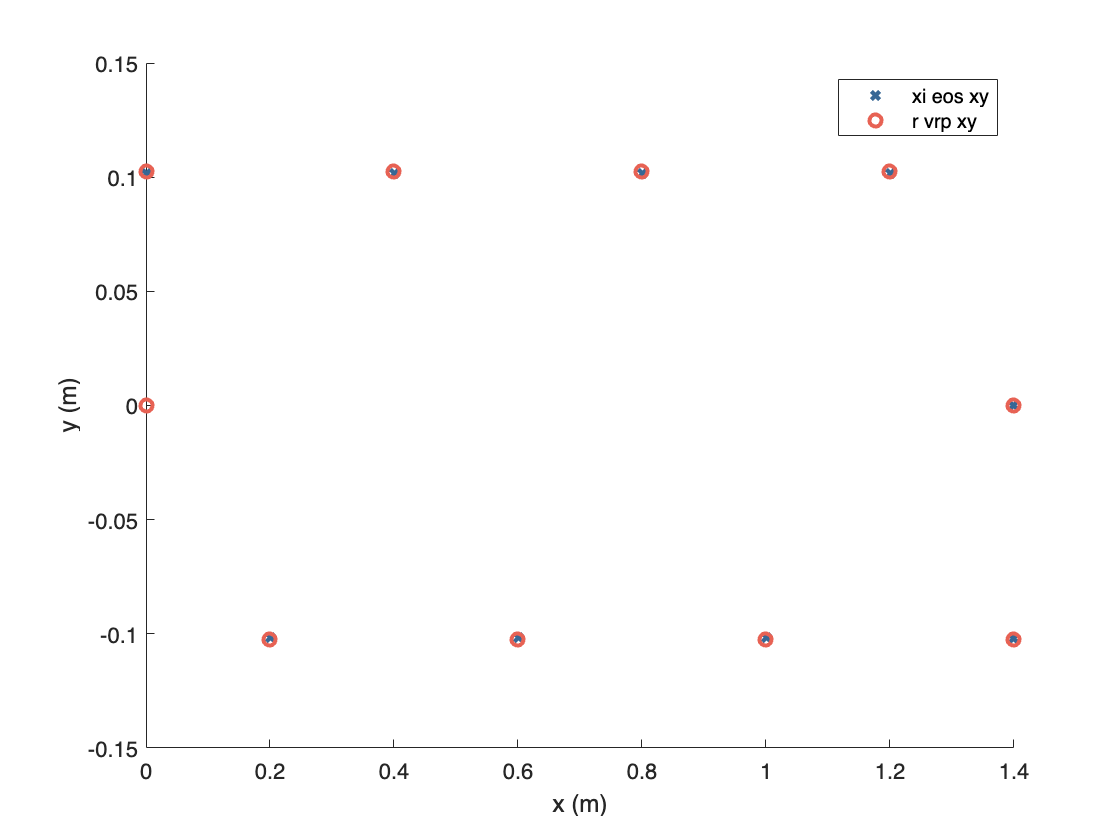

% 绘图部分
% 设置基础颜色
colors = [55, 103, 149; 114, 188, 213; 255, 208, 111; 231, 98, 84; 239, 138, 71];
color1 = colors(1, :) / 255;
color2 = colors(2, :) / 255;
color3 = colors(3, :) / 255;
color4 = colors(4, :) / 255;
color5 = colors(5, :) / 255;

% 展示DCM的终点和期望VRP之间的关系
figure();
hold on
plot(xi_eos(1,:), xi_eos(2,:), 'x','Color', color1, 'LineWidth', 2)
plot(r_vrp(1,:), r_vrp(2,:), 'ro','Color', color4, 'LineWidth', 2)
xlabel('x (m)')
ylabel('y (m)')
legend({'xi eos xy', 'r vrp xy'},'Location','northeast')

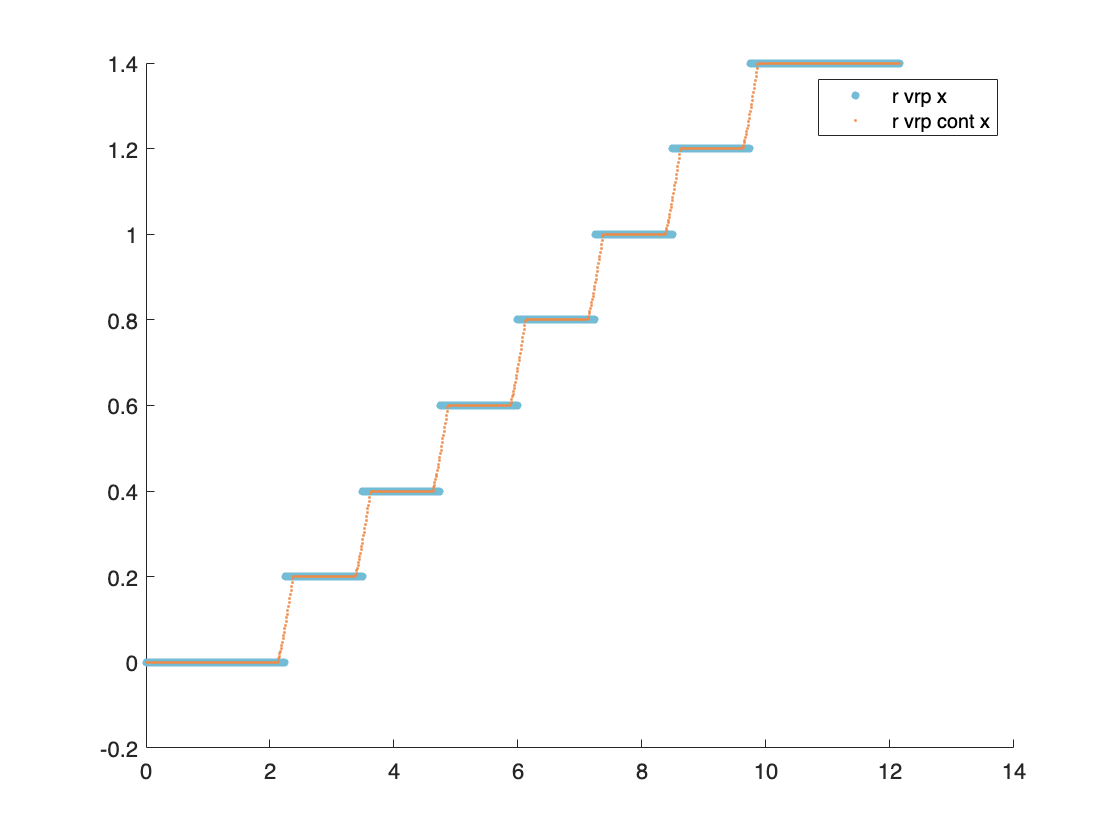

% 展示VRP的变化
figure();
hold on;
plot(t, r_vrp_disc(1,:),'.', 'Color', color2, 'MarkerSize', 12)
plot(t, r_vrp_cont(1,:),'.', 'Color', color5, 'MarkerSize', 4)
legend({'r vrp x', 'r vrp cont x'},'Location','northeast')

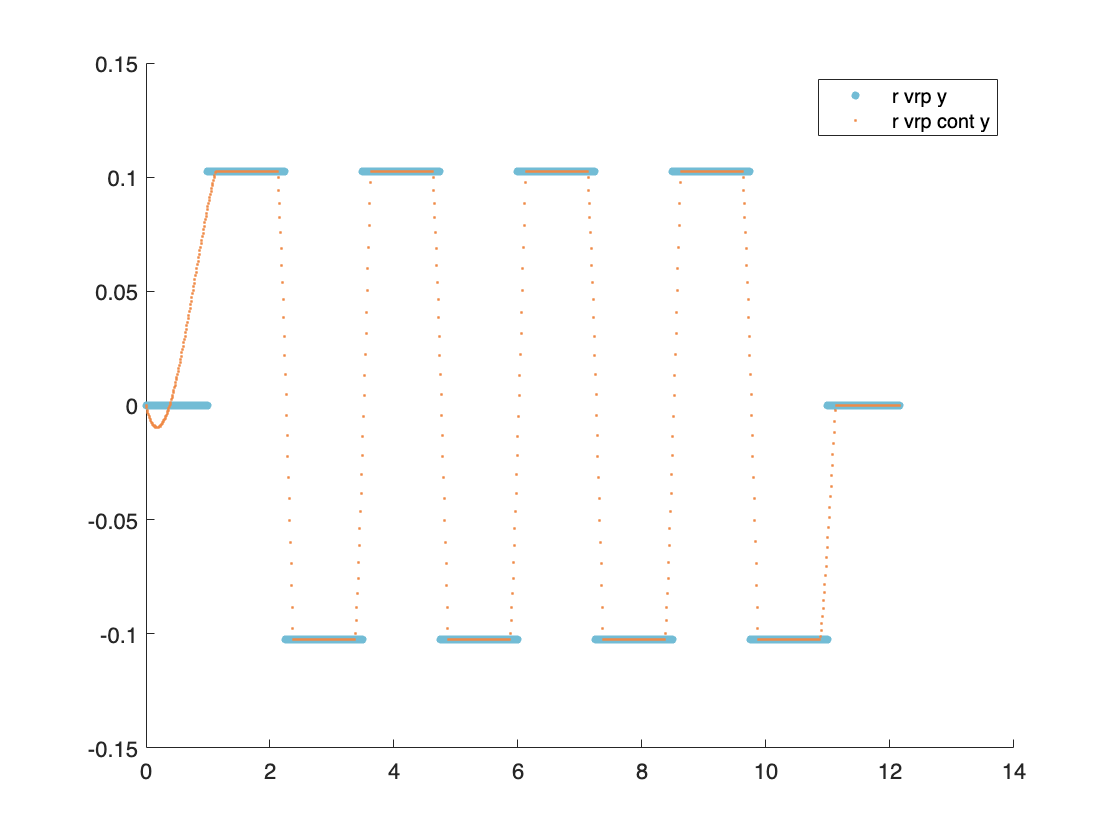

figure();
hold on;
plot(t, r_vrp_disc(2,:),'.', 'Color', color2, 'MarkerSize', 12)
plot(t, r_vrp_cont(2,:),'.', 'Color', color5, 'MarkerSize', 4)
legend({'r vrp y', 'r vrp cont y'},'Location','northeast')

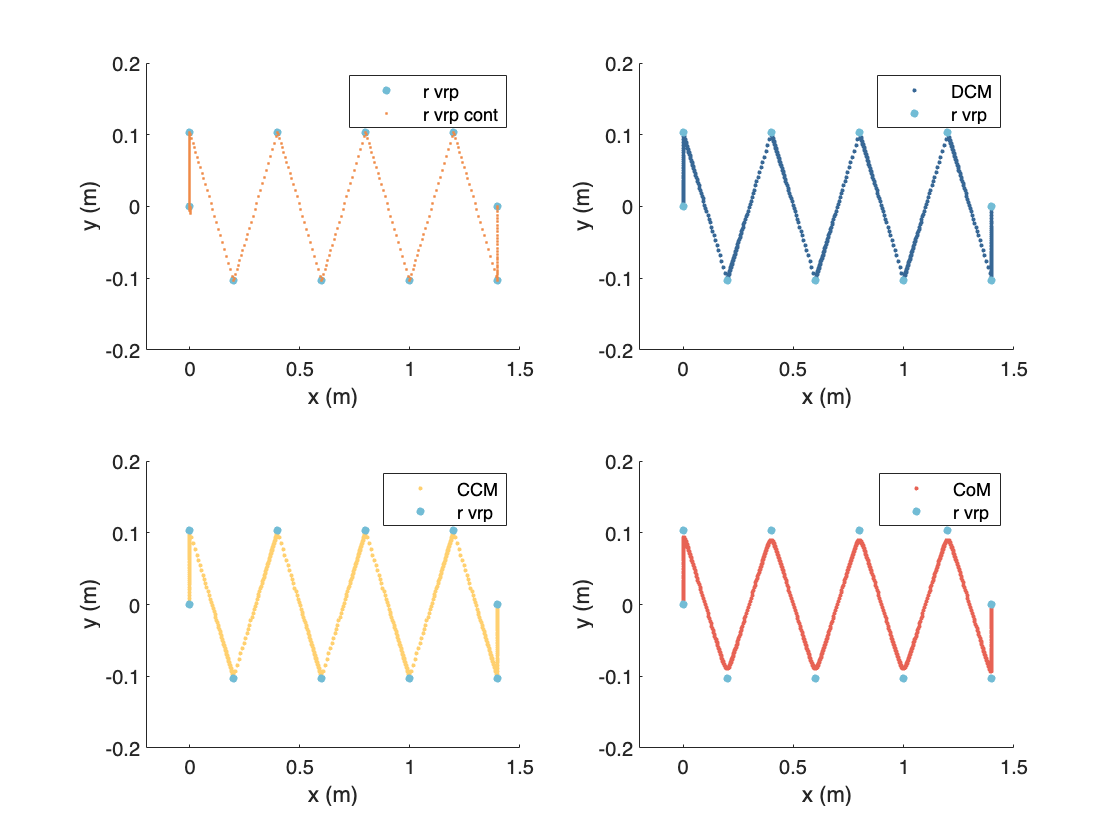

% 展示DCM中存在的两个一阶动力学
figure();
subplot(2,2,1);
hold on;
plot(r_vrp_disc(1,:), r_vrp_disc(2,:), '.', 'Color', color2, 'MarkerSize', 12)
plot(r_vrp_cont(1,:), r_vrp_cont(2,:), '.', 'Color', color5, 'MarkerSize', 4)
xlabel('x (m)')
ylabel('y (m)')
xlim([-0.2, 1.5]);
ylim([-0.2, 0.2]);
legend({'r vrp', 'r vrp cont'},'Location','northeast')
subplot(2,2,2);
hold on;
plot(xi_ref_d(1,:), xi_ref_d(2,:), '.', 'Color', color1)
plot(r_vrp_disc(1,:), r_vrp_disc(2,:), '.', 'Color', color2, 'MarkerSize', 12)
xlabel('x (m)')
ylabel('y (m)')
xlim([-0.2, 1.5]);
ylim([-0.2, 0.2]);
legend({'DCM', 'r vrp'},'Location','northeast')
subplot(2,2,3);
hold on;
plot(xi_hat_ref_d(1,:), xi_hat_ref_d(2,:), '.', 'Color', color3)
plot(r_vrp_disc(1,:), r_vrp_disc(2,:), '.', 'Color', color2, 'MarkerSize', 12)
xlabel('x (m)')
ylabel('y (m)')
xlim([-0.2, 1.5]);
ylim([-0.2, 0.2]);
legend({'CCM', 'r vrp'},'Location','northeast')
subplot(2,2,4);
hold on;
plot(com_ref_d(1,:), com_ref_d(2,:), '.', 'Color', color4)
plot(r_vrp_disc(1,:), r_vrp_disc(2,:), '.', 'Color', color2, 'MarkerSize', 12)
xlabel('x (m)')
ylabel('y (m)')
xlim([-0.2, 1.5]);
ylim([-0.2, 0.2]);
legend({'CoM', 'r vrp'},'Location','northeast')

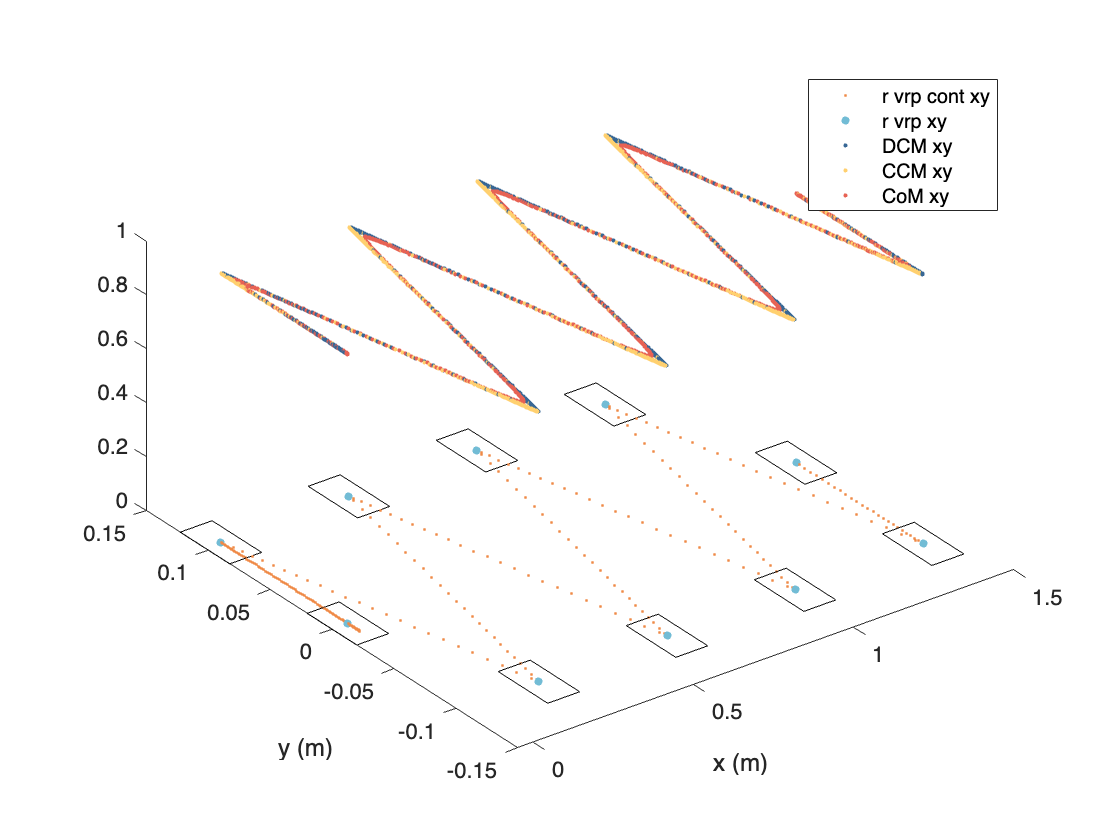

figure();
hold on
plot(r_vrp_cont(1,:), r_vrp_cont(2,:), '.', 'Color', color5, 'MarkerSize', 4)
plot(r_vrp_disc(1,:), r_vrp_disc(2,:), '.', 'Color', color2, 'MarkerSize', 12)
for i=1:size(r_vrp_disc(1,:),2)
    rectangle('Position',[r_vrp_disc(1,i)-0.05,r_vrp_disc(2,i)-0.02,0.1,0.04]);
end
plot3(xi_ref_d(1,:), xi_ref_d(2,:), ones(size(xi_ref_d(1,:))), '.', 'Color', color1)
plot3(xi_hat_ref_d(1,:), xi_hat_ref_d(2,:), ones(size(xi_hat_ref_d(1,:))), '.', 'Color', color3)
plot3(com_ref_d(1,:), com_ref_d(2,:), ones(size(com_ref_d(1,:))), '.', 'Color', color4)
xlabel('x (m)')
ylabel('y (m)')
legend({'r vrp cont xy', 'r vrp xy', 'DCM xy', 'CCM xy', 'CoM xy'},'Location','northeast')
view([-36.843 47.775])

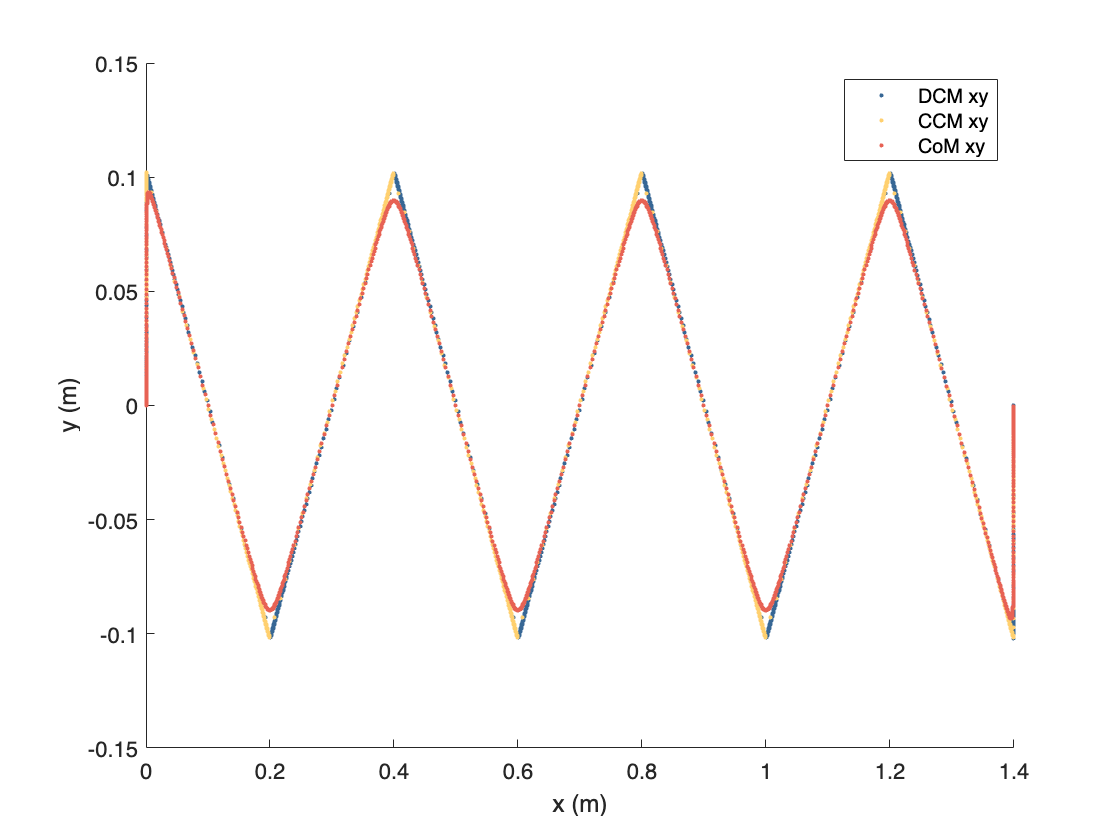

figure();
hold on
plot(xi_ref_d(1,:), xi_ref_d(2,:), '.', 'Color', color1)
plot(xi_hat_ref_d(1,:), xi_hat_ref_d(2,:), '.', 'Color', color3)
plot(com_ref_d(1,:), com_ref_d(2,:), '.', 'Color', color4)
xlabel('x (m)')
ylabel('y (m)')
legend({'DCM xy', 'CCM xy', 'CoM xy'},'Location','northeast')

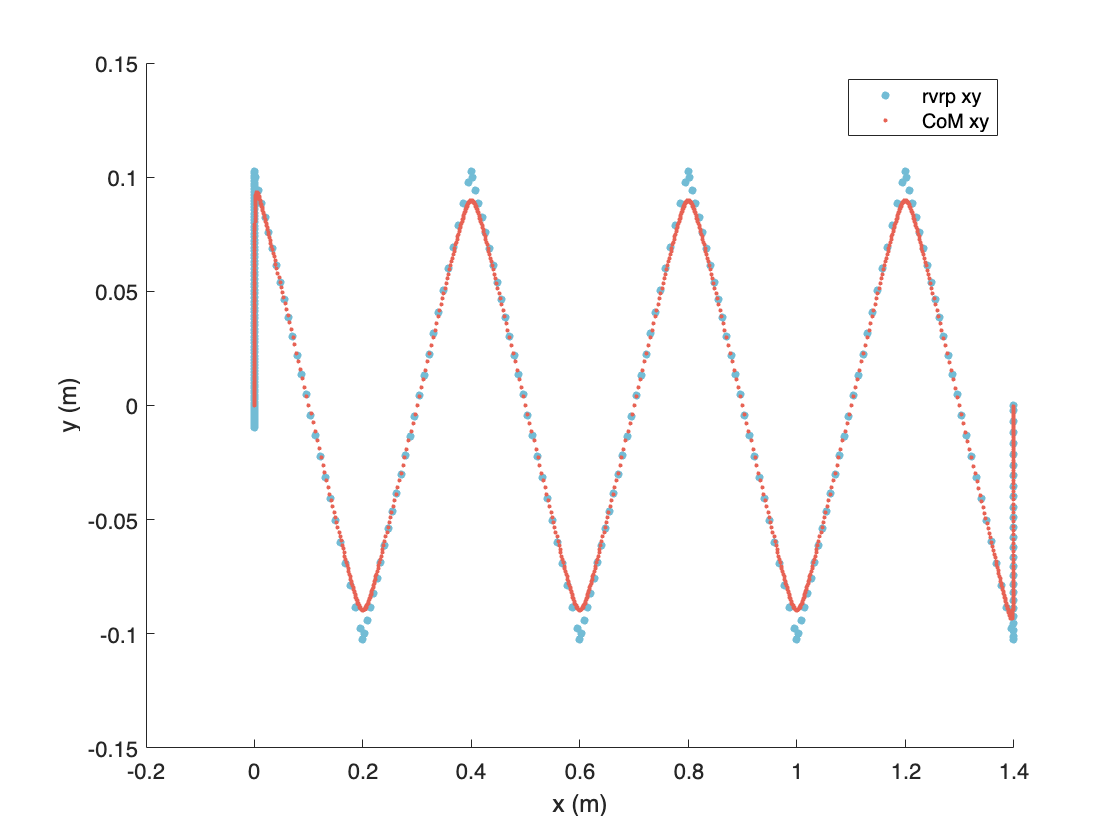

figure();
hold on
plot(r_vrp_cont(1,:), r_vrp_cont(2,:), '.', 'Color', color2, 'MarkerSize', 12)
plot(com_cont_ref_d(1,:), com_cont_ref_d(2,:), '.', 'Color', color4)
xlabel('x (m)')
ylabel('y (m)')
legend({'rvrp xy', 'CoM xy'},'Location','northeast')

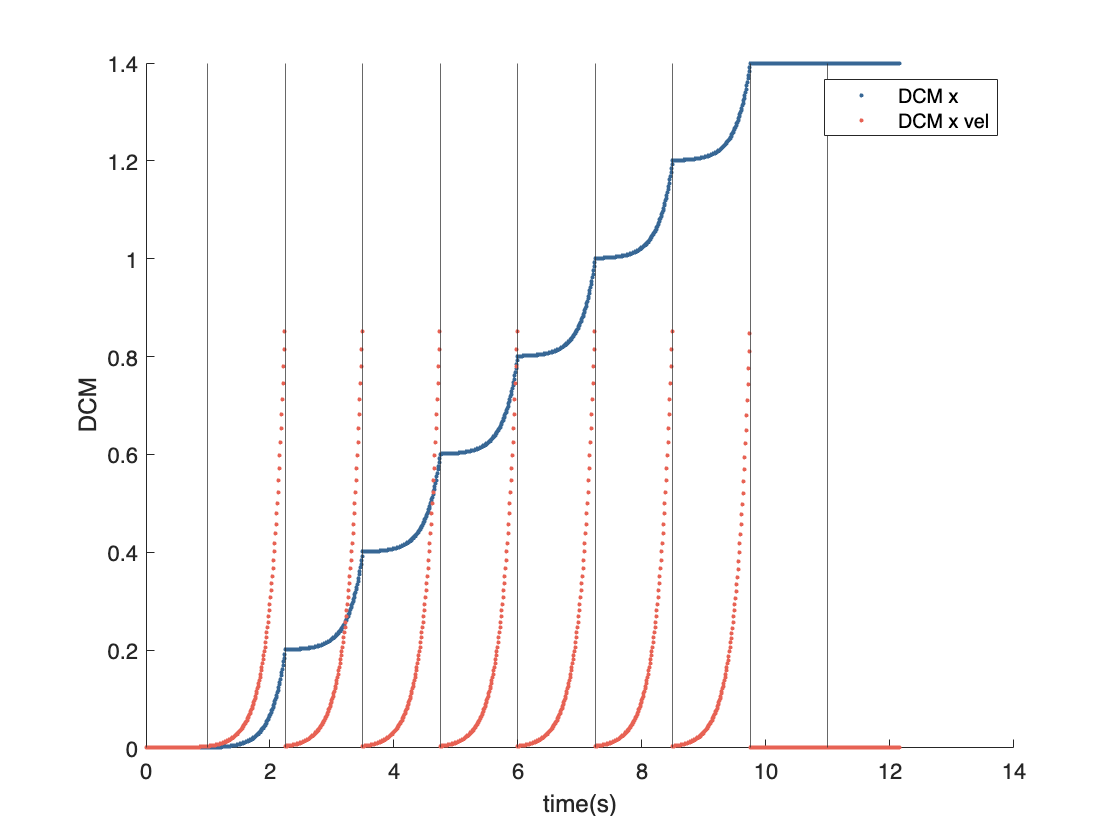

% 展示DCM x方向位置、速度的变化
figure();
hold on
plot(t, xi_ref_d(1,:),'.', 'Color', color1)
plot(t, xi_vel_ref_d(1,:),'.', 'Color', color4);
t_start = 0.0;
for(i = 1:size(t_step,2))
    xline(t_start);
    t_start = t_start + t_step(i);
end
xlabel('time(s)')
ylabel('DCM')
legend({'DCM x','DCM x vel'},'Location','northeast')

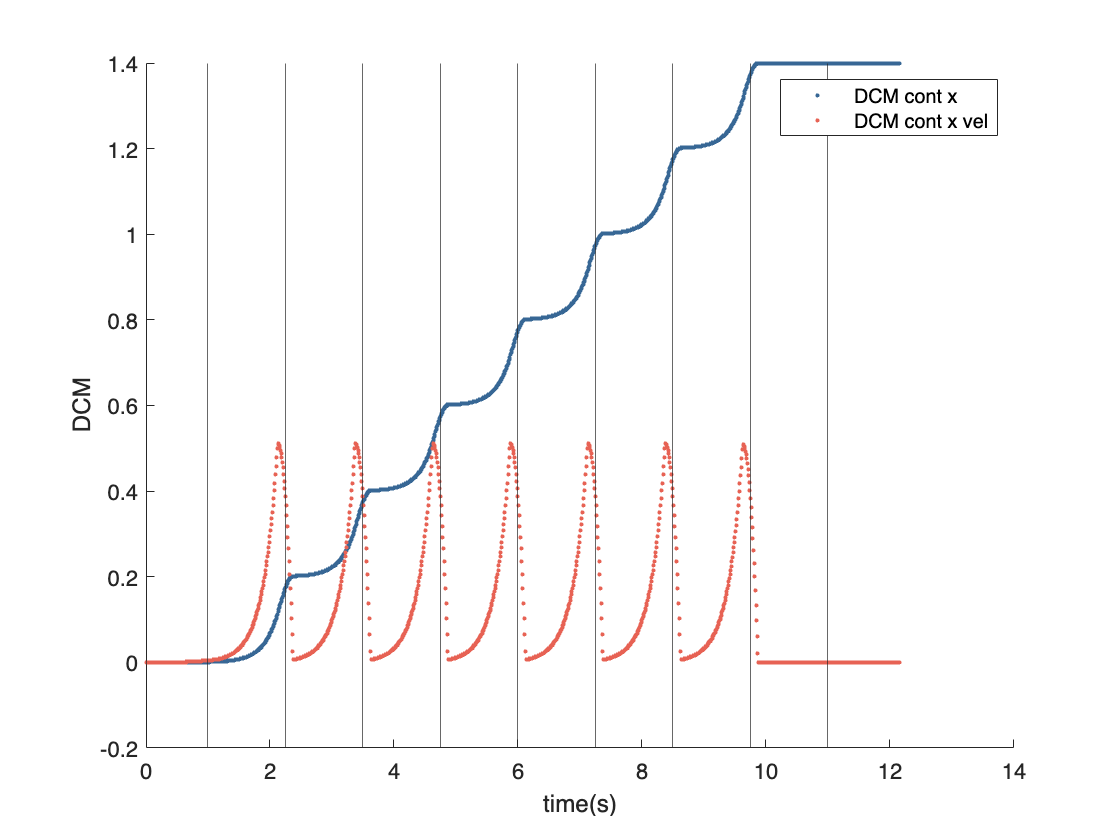

% 展示DSP DCM x方向位置、速度的变化
figure();
hold on
plot(t, xi_ref_hybrid_d(1,:),'.', 'Color', color1)
plot(t, xi_vel_ref_hybrid_d(1,:),'.', 'Color', color4);
t_start = 0.0;
for(i = 1:size(t_step,2))
    xline(t_start);
    t_start = t_start + t_step(i);
end
xlabel('time(s)')
ylabel('DCM')
legend({'DCM cont x','DCM cont x vel'},'Location','northeast')

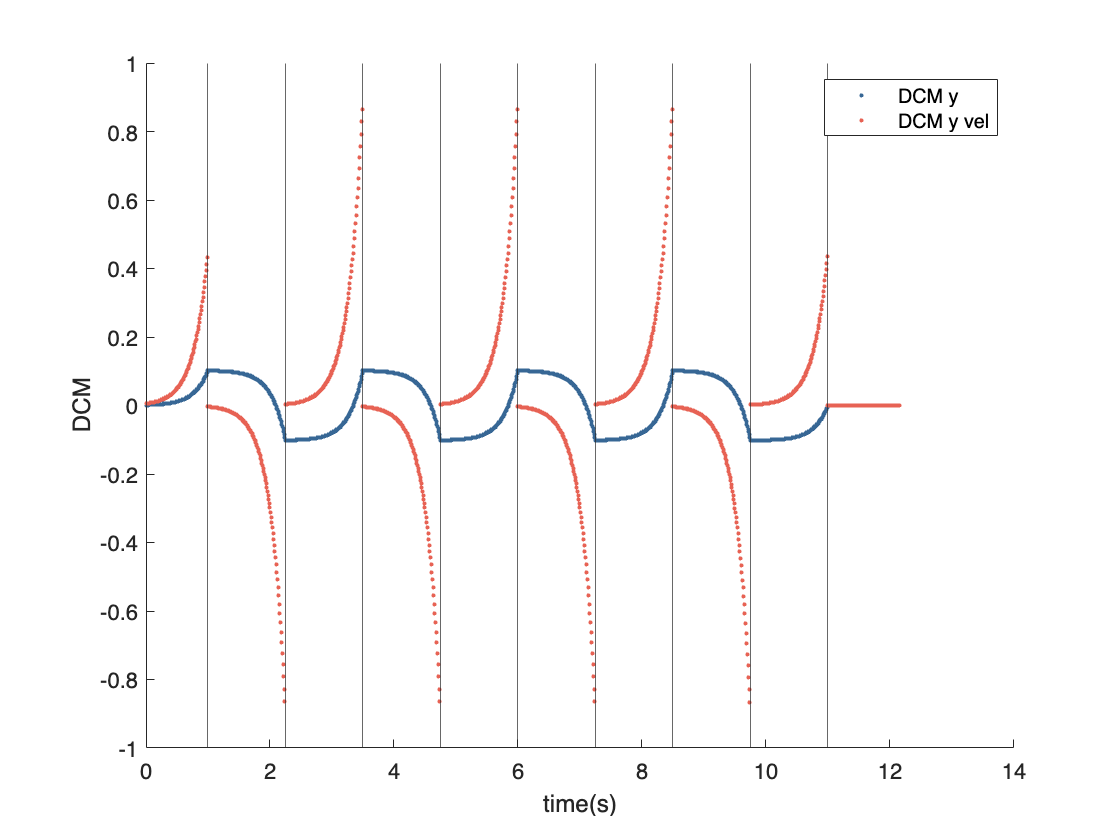

% 展示DCM y方向位置、速度的变化
figure();
hold on
plot(t, xi_ref_d(2,:),'.', 'Color', color1)
plot(t, xi_vel_ref_d(2,:),'.', 'Color', color4);
t_start = 0.0;
for(i = 1:size(t_step,2))
    xline(t_start);
    t_start = t_start + t_step(i);
end
xlabel('time(s)')
ylabel('DCM')
legend({'DCM y','DCM y vel'},'Location','northeast')

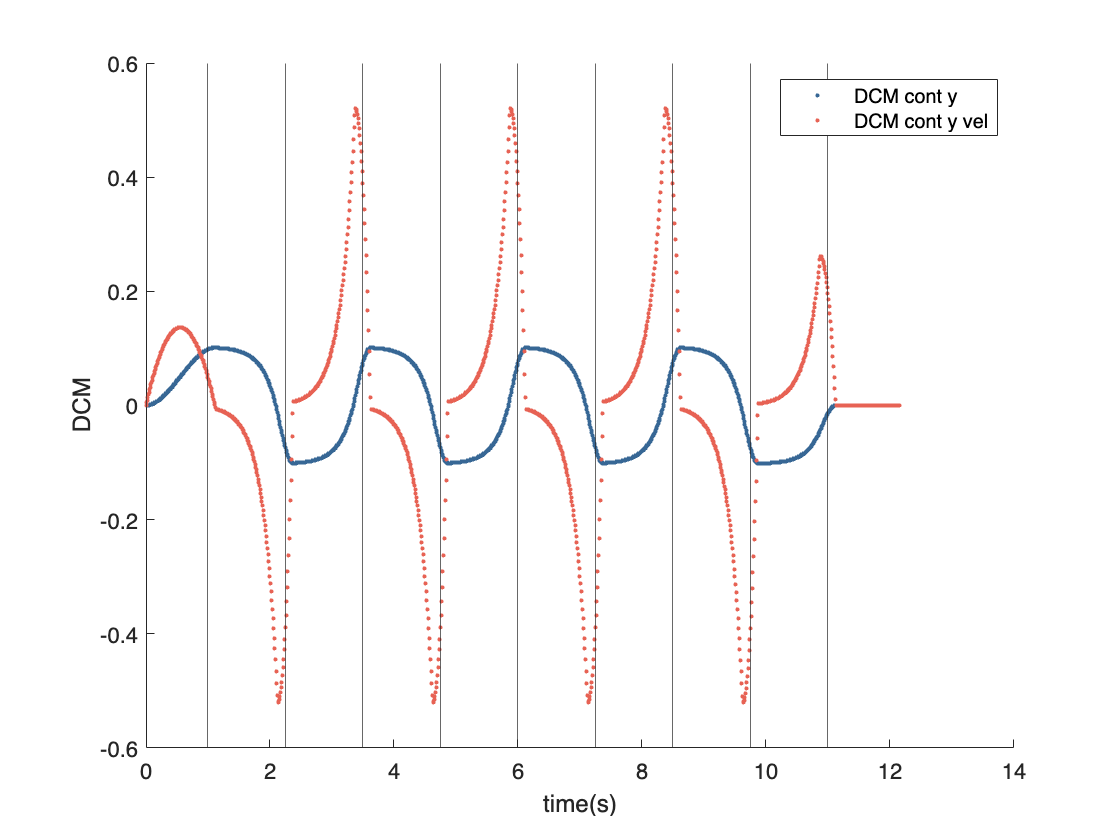

% 展示DSP DCM y方向位置、速度的变化
figure();
hold on
plot(t, xi_ref_hybrid_d(2,:),'.', 'Color', color1)
plot(t, xi_vel_ref_hybrid_d(2,:),'.', 'Color', color4);
t_start = 0.0;
for(i = 1:size(t_step,2))
    xline(t_start);
    t_start = t_start + t_step(i);
end
xlabel('time(s)')
ylabel('DCM')
legend({'DCM cont y','DCM cont y vel'},'Location','northeast')

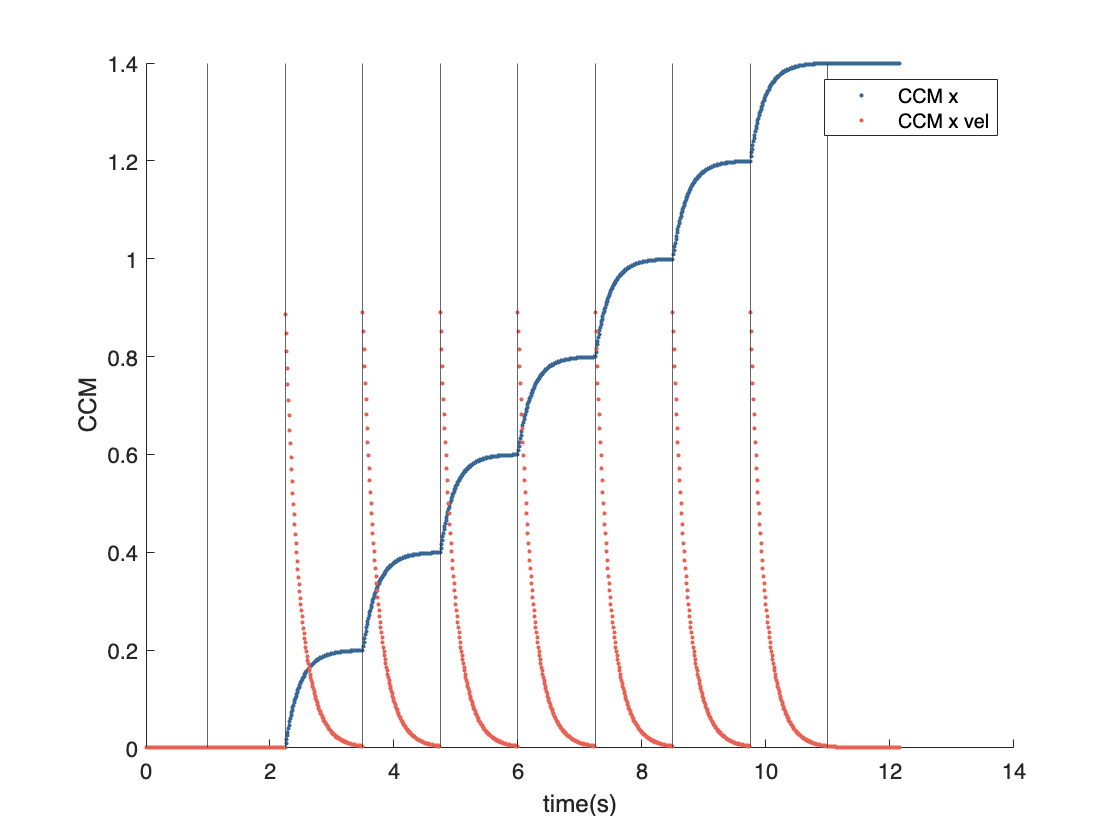

% 展示CCMx方向位置、速度的变化
figure();
hold on
plot(t, xi_hat_ref_d(1,:),'.', 'Color', color1)
plot(t, xi_hat_vel_ref_d(1,:),'.', 'Color', color4);
t_start = 0.0;
for(i = 1:size(t_step,2))
    xline(t_start);
    t_start = t_start + t_step(i);
end
xlabel('time(s)')
ylabel('CCM')
legend({'CCM x','CCM x vel'},'Location','northeast')

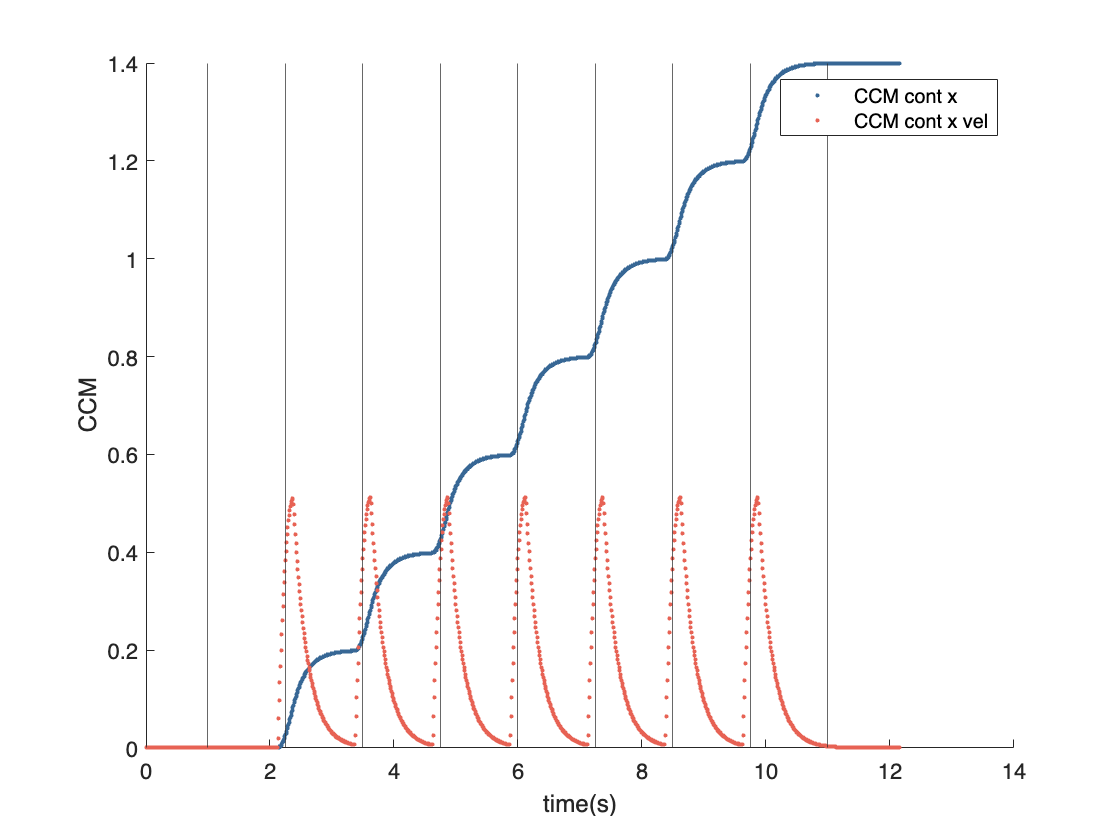

% 展示DSP CCMx方向位置、速度的变化
figure();
hold on
plot(t, xi_hat_ref_hybrid_d(1,:),'.', 'Color', color1)
plot(t, xi_hat_vel_ref_hybrid_d(1,:),'.', 'Color', color4);
t_start = 0.0;
for(i = 1:size(t_step,2))
    xline(t_start);
    t_start = t_start + t_step(i);
end
xlabel('time(s)')
ylabel('CCM')
legend({'CCM cont x','CCM cont x vel'},'Location','northeast')

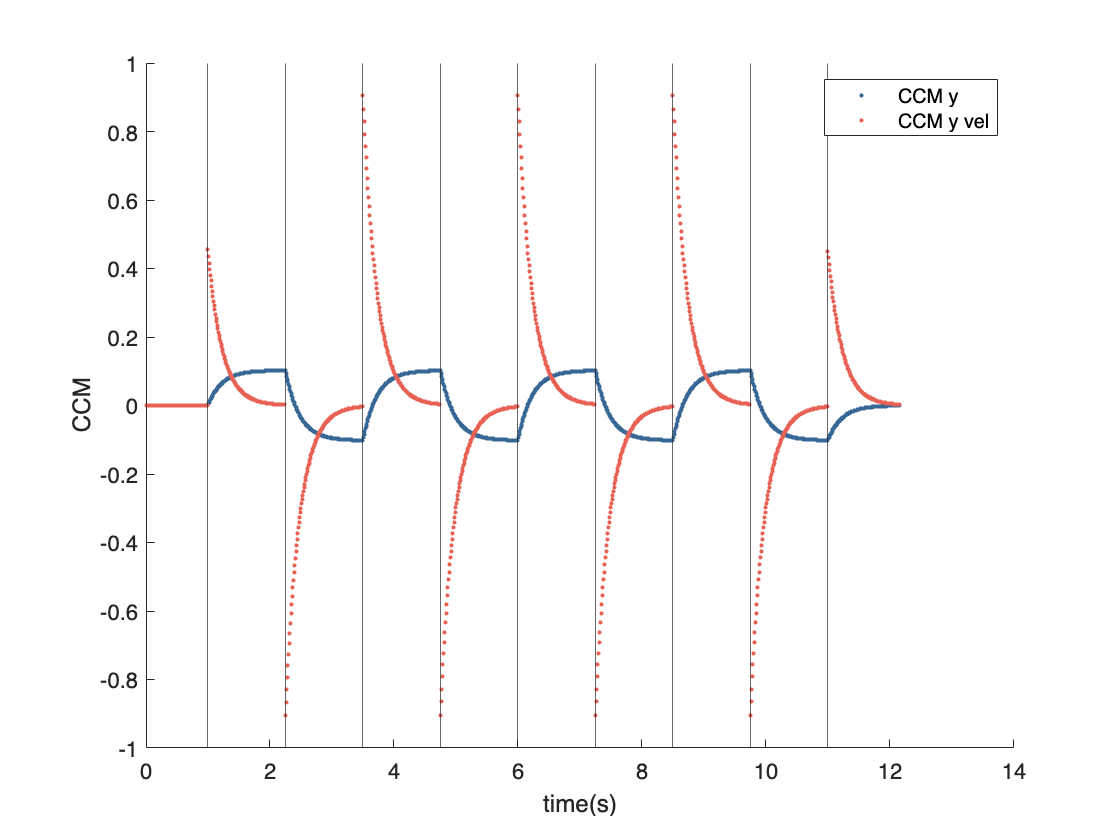

% 展示CCMy方向位置、速度的变化
figure();
hold on
plot(t, xi_hat_ref_d(2,:),'.', 'Color', color1);
plot(t, xi_hat_vel_ref_d(2,:),'.', 'Color', color4);
t_start = 0.0;
for(i = 1:size(t_step,2))
    xline(t_start);
    t_start = t_start + t_step(i);
end
xlabel('time(s)')
ylabel('CCM')
legend({'CCM y','CCM y vel'},'Location','northeast')

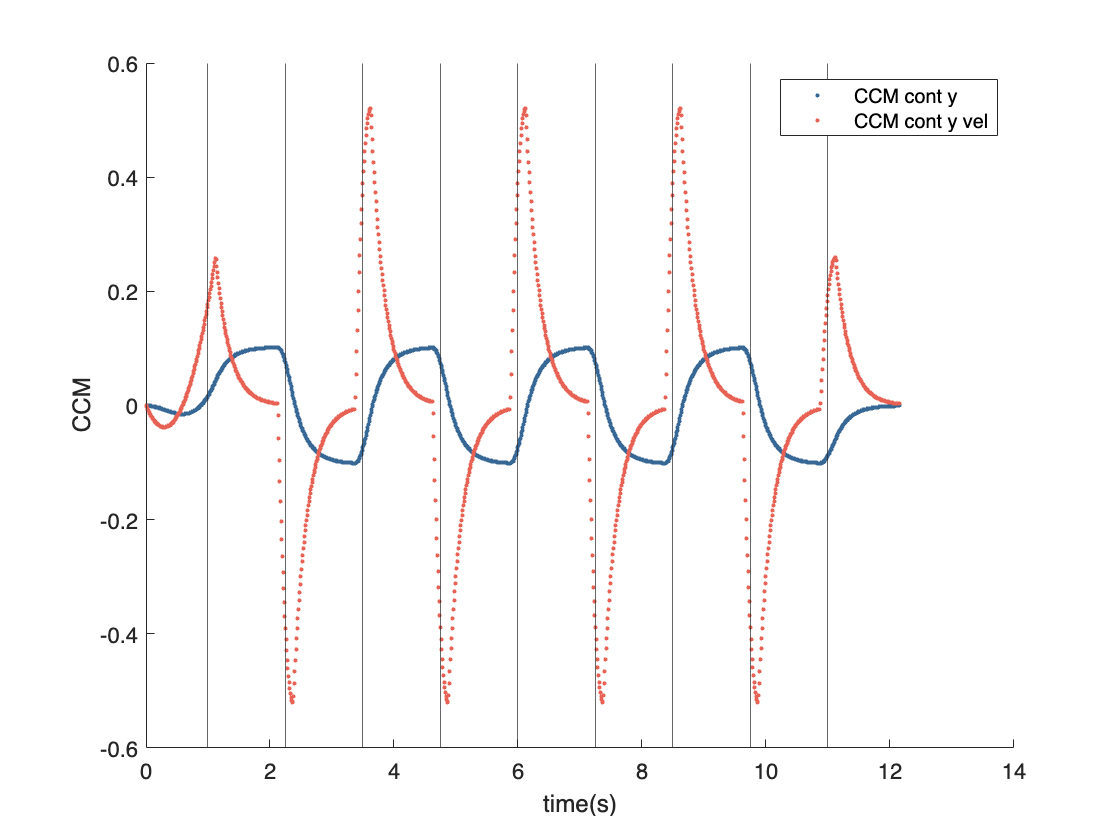

% 展示DSP CCMy方向位置、速度的变化
figure();
hold on
plot(t, xi_hat_ref_hybrid_d(2,:),'.', 'Color', color1);
plot(t, xi_hat_vel_ref_hybrid_d(2,:),'.', 'Color', color4);
t_start = 0.0;
for(i = 1:size(t_step,2))
    xline(t_start);
    t_start = t_start + t_step(i);
end
xlabel('time(s)')
ylabel('CCM')
legend({'CCM cont y','CCM cont y vel'},'Location','northeast')

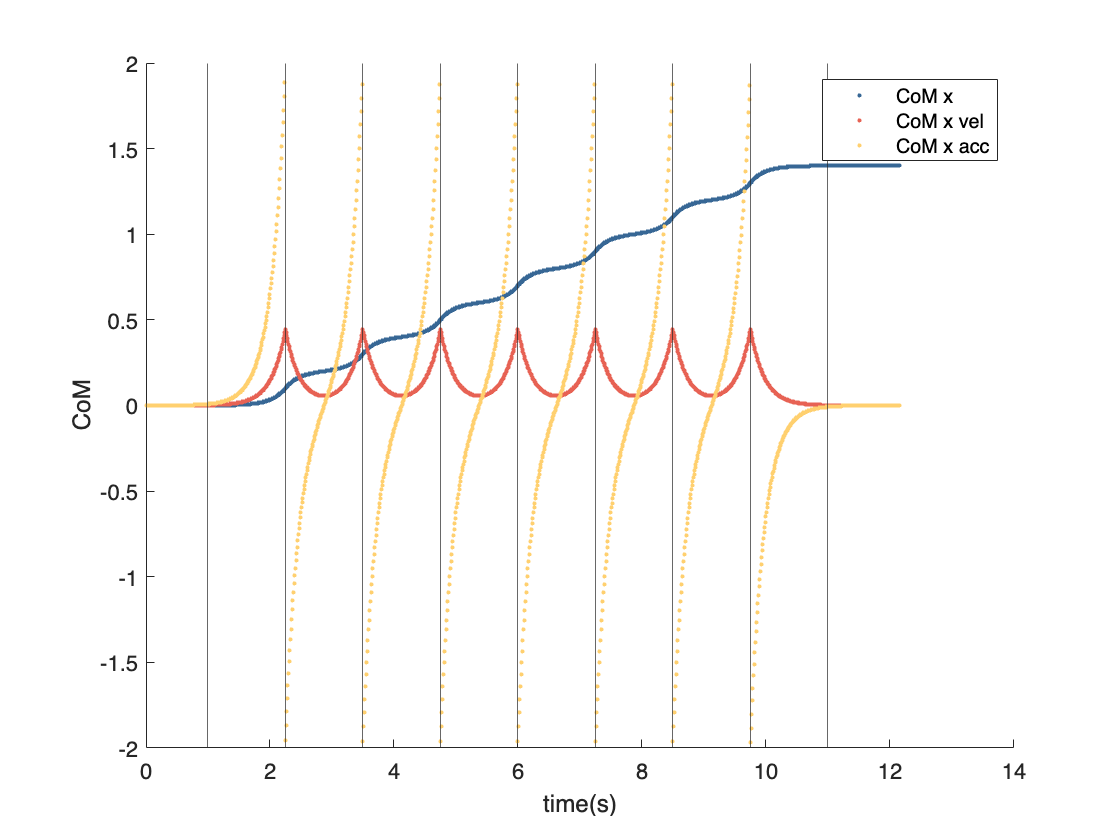

% 展示CoM x方向位置、速度的变化
figure();
hold on
plot(t, com_ref_d(1,:),'.', 'Color', color1)
plot(t, com_vel_ref_d(1,:),'.', 'Color', color4);
plot(t, com_acc_ref_d(1,:),'.', 'Color', color3);
t_start = 0.0;
for(i = 1:size(t_step,2))
    xline(t_start);
    t_start = t_start + t_step(i);
end
xlabel('time(s)')
ylabel('CoM')
legend({'CoM x','CoM x vel','CoM x acc'},'Location','northeast')

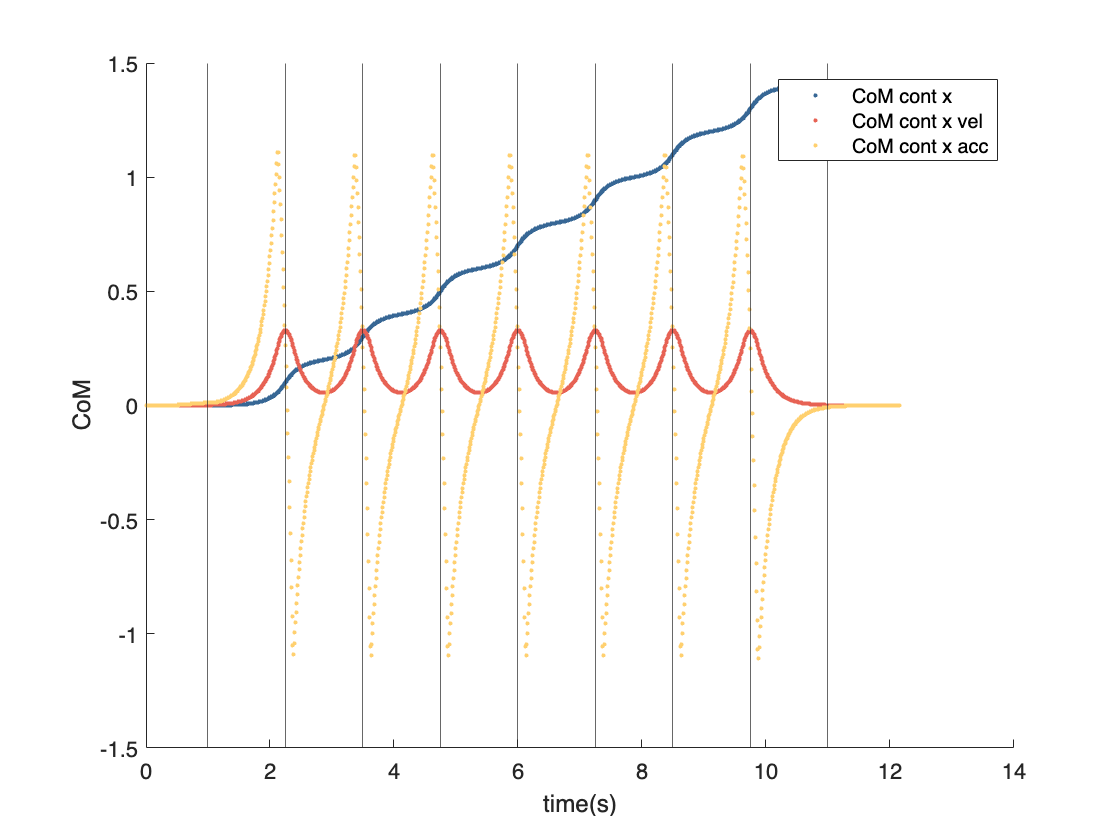

% 展示DSP CoM x方向位置、速度的变化
figure();
hold on
plot(t, com_cont_ref_d(1,:),'.', 'Color', color1)
plot(t, com_cont_vel_ref_d(1,:),'.', 'Color', color4);
plot(t, com_cont_acc_ref_d(1,:),'.', 'Color', color3);
t_start = 0.0;
for(i = 1:size(t_step,2))
    xline(t_start);
    t_start = t_start + t_step(i);
end
xlabel('time(s)')
ylabel('CoM')
legend({'CoM cont x','CoM cont x vel','CoM cont x acc'},'Location','northeast')

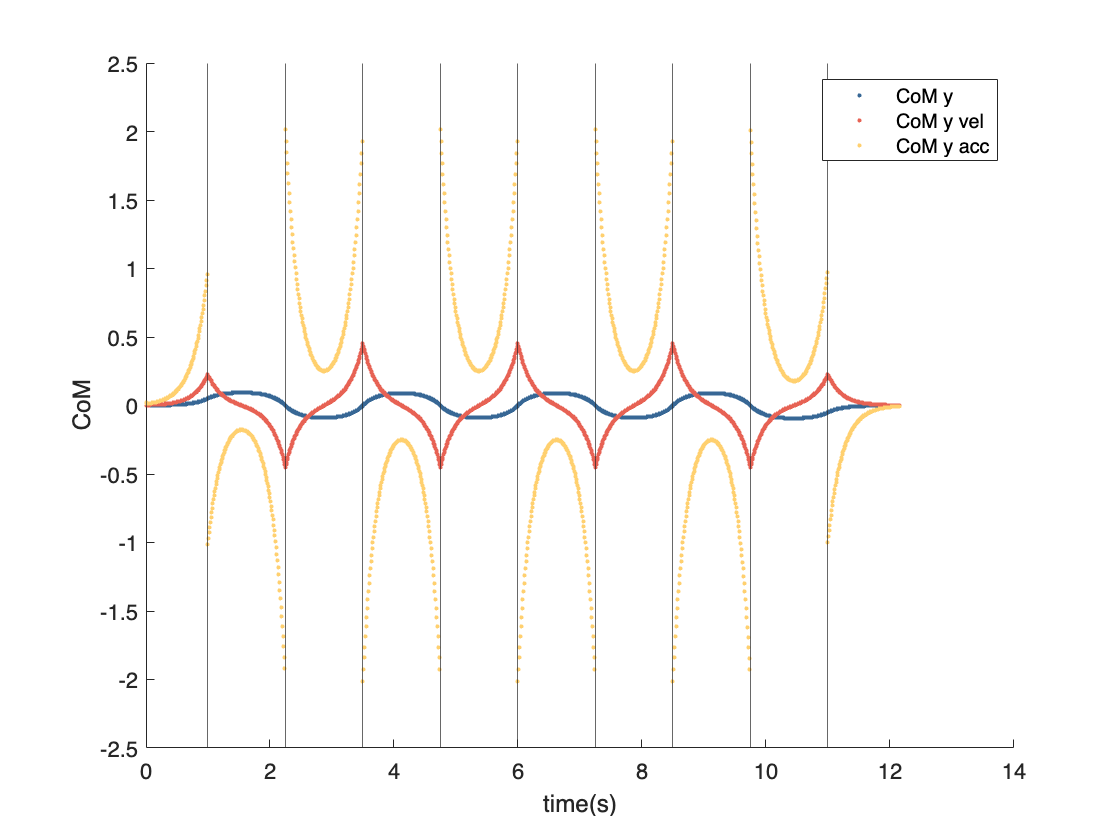

% 展示CoM y方向位置、速度、加速度的变化
figure();
hold on
plot(t, com_ref_d(2,:),'.', 'Color', color1)
plot(t, com_vel_ref_d(2,:),'.', 'Color', color4);
plot(t, com_acc_ref_d(2,:),'.', 'Color', color3);
t_start = 0.0;
for(i = 1:size(t_step,2))
    xline(t_start);
    t_start = t_start + t_step(i);
end
xlabel('time(s)')
ylabel('CoM')
legend({'CoM y','CoM y vel','CoM y acc'},'Location','northeast')

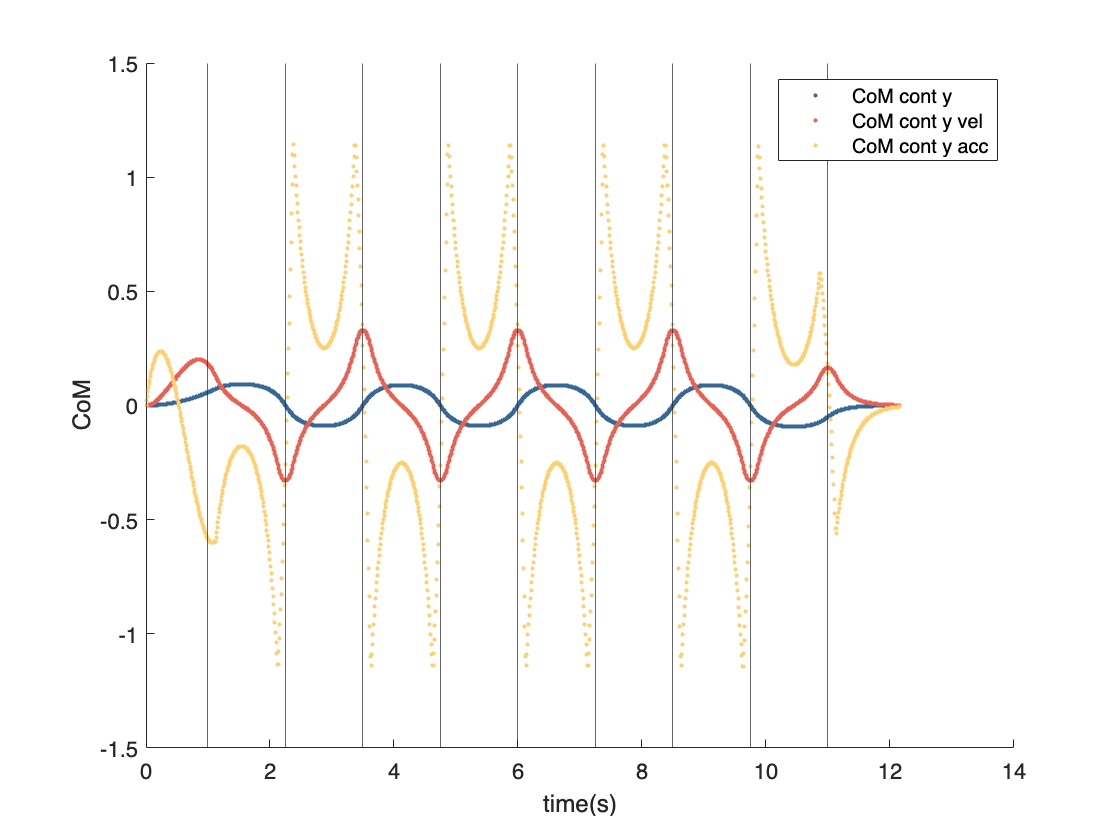

% 展示DSP CoM y方向位置、速度的变化
figure();
hold on
plot(t, com_cont_ref_d(2,:),'.', 'Color', color1)
plot(t, com_cont_vel_ref_d(2,:),'.', 'Color', color4);
plot(t, com_cont_acc_ref_d(2,:),'.', 'Color', color3);
t_start = 0.0;
for(i = 1:size(t_step,2))
    xline(t_start);
    t_start = t_start + t_step(i);                                  
end
xlabel('time(s)')
ylabel('CoM')
legend({'CoM cont y','CoM cont y vel','CoM cont y acc'},'Location','northeast')

## 函数部分

function t_traj_length = get_trajectory_length(t_step)
    % 求行走的总时长
    t_traj_length = 0.0;
    for(i = 1:size(t_step,2))
        t_traj_length = t_traj_length + t_step(i);
    end
end

function step_index = which_step_index(t_input, t_step)
    % 判断该时间处在第几步
    t_trajectory_length = get_trajectory_length(t_step);
    t_input = max(min(t_input, t_trajectory_length), 0.0);
    
    t_step_start = 0.0;
    step_index = 1;
    for(i = 1:size(t_step,2))
        t_step_end = t_step_start + t_step(i);
        if (t_step_start <= t_input) && (t_input < t_step_end)
           step_index = i;
           return
        end
        t_step_start = t_step_end;
    end
    
    step_index = size(t_step, 2);
end

function step_index = which_hybrid_step_index(t_input, t_step, t_ds_vec, alpha)
    % 判断DSP模式下该时间处在第几步
    t_trajectory_length = get_trajectory_length(t_step);
    t_input = max(min(t_input, t_trajectory_length), 0.0);

    for(i = 1:size(t_step,2))
        if (i < size(t_step,2))
            t_ds_step_start = get_DS_start_time(i, t_step, t_ds_vec, alpha);
            t_step_end = get_DS_start_time(i+1, t_step, t_ds_vec, alpha);        
            
            if (i == 1)
                t_step_end = get_DS_end_time(i, t_step, t_ds_vec, alpha);
            end
            
            if (t_ds_step_start <= t_input) && (t_input < t_step_end)
               step_index = i;
               return
            end
        else
            break
        end
    end
    
    step_index = size(t_step, 2);
end

function t_local_start = get_t_exp_start(step_index, t_step)
    % 获得这一步的开始时间 
    t_local_start = 0.0;
    for(i = 1:step_index)
        if (i < step_index)
            t_local_start = t_local_start + t_step(i);
        else
            break
        end
    end
end

function t_ds_start = get_DS_start_time(step_index, t_step, t_ds_vec, alpha)
    % 获得双足支撑阶段的开始时间
    t_ds_start = get_t_exp_start(step_index, t_step);
    if (step_index > 1)
        t_ds_start = t_ds_start - alpha*t_ds_vec(step_index);
    end
end

function t_ds_end = get_DS_end_time(step_index, t_step, t_ds_vec, alpha)
    % 获得双足支撑阶段的结束时间
    t_ds_start = get_DS_start_time(step_index, t_step, t_ds_vec, alpha);
    t_ds_end = t_ds_start + t_ds_vec(step_index);
end

function P = get_polynomial_matrix(Ts, xi_ini, xi_ini_vel, xi_end, xi_end_vel)
    % 计算双足支撑的插值函数    
    Pmat = zeros(4,4);
    boundMat = [xi_ini'; xi_ini_vel'; xi_end'; xi_end_vel'];
    Pmat(1, :) = [2.0/(Ts^3), 1/(Ts^2), -2/(Ts^3), 1/(Ts^2) ];
    Pmat(2, :) = [-3.0/(Ts^2), -2.0/(Ts), 3/(Ts^2), -1/(Ts) ];
    Pmat(3, :) = [0, 1, 0, 0];
    Pmat(4, :) = [1, 0, 0, 0];
    P = Pmat*boundMat;
end

function xi_DS_poly = get_xi_DS_poly(t, Ts, P_mat)
    % 计算双足支撑时间内的DCM轨迹
    xi_DS_poly = zeros(3, size(t,2)); 
    % 将输入时间截断至Ts
    for (i = 1:size(t,2))
        t_input = max(min(t(i), Ts), 0.0);
        time_vec = [t_input^3, t_input^2, t_input, 1];
        xi_DS_poly(:,i) = time_vec*P_mat;
    end
end

function xi_vel_DS_poly = get_xi_vel_DS_poly(t, Ts, P_mat)
    % 计算双足支撑阶段的DCM速度 
    xi_vel_DS_poly = zeros(3, size(t,2));    
    for (i = 1:size(t,2))
        t_input = max(min(t(i), Ts), 0.0);
        time_vec = [3*(t_input^2), 2*(t_input), 1, 0];
        xi_vel_DS_poly(:,i) = time_vec*P_mat;
    end
end

function xi_d = get_xi_d(t, t_step, b, r_vrp, xi_eos)
    % 论文中Eq.19，计算一步之内的DCM期望值
    xi_d = r_vrp + exp((1/b)*(t-t_step)).*(xi_eos - r_vrp);
end

function xi_ref_d = get_xi_ref_d(t, t_step, b, r_vrp, xi_eos)
    % 对仿真中的每一帧，判定其属于哪一步，再计算其DCM期望值
    xi_ref_d = zeros(3, size(t,2));
    t_local_start = 0.0;
    for(i = 1:size(xi_ref_d,2))
        step_index = which_step_index(t(i), t_step);
        t_local_start = get_t_exp_start(step_index, t_step);
        xi_ref_d(:, i) = get_xi_d(t(i) - t_local_start, t_step(step_index), b, r_vrp(:, step_index), xi_eos(:, step_index));
    end
end

function xi_ref_hybrid_d = get_xi_ref_hybrid_d(t, t_step, b, r_vrp, xi_eos, t_ds_vec, alpha, P_mats)
    % 在带有双足支撑的情况下，对于非双足支撑阶段，利用公式进行计算，对于双足支撑阶段，使用插值函数得出
    xi_ref_hybrid_d = zeros(3, size(t,2));
    t_local_start = 0.0;
    for(i = 1:size(xi_ref_hybrid_d,2))
        step_index = which_hybrid_step_index(t(i), t_step, t_ds_vec, alpha);
        if (t(i) <= get_DS_end_time(step_index, t_step, t_ds_vec, alpha))
            t_local_start = t(i) - get_DS_start_time(step_index, t_step, t_ds_vec, alpha);
            xi_ref_hybrid_d(:, i) = get_xi_DS_poly(t_local_start, t_ds_vec(step_index), P_mats(:,:, step_index));
        else
            t_local_start = t(i) - get_t_exp_start(step_index, t_step);
            xi_ref_hybrid_d(:, i) = get_xi_d(t_local_start, t_step(step_index), b, r_vrp(:, step_index), xi_eos(:, step_index));
        end
    end
end

function xi_vel_d = get_xi_vel_d(t, t_step, b, r_vrp, xi_eos)
    % 对Eq.19求导可以得到，计算一步之内的DCM期望速度
    xi_vel_d = (1/b)*exp((1/b)*(t-t_step)).*(xi_eos - r_vrp);
end

function xi_vel_ref_d = get_xi_vel_ref_d(t, t_step, b, r_vrp, xi_eos)
    % 对仿真中的每一帧，判定其属于哪一步，再计算其DCM期望速度
    xi_vel_ref_d = zeros(3, size(t,2));
    t_local_start = 0.0;
    for(i = 1:size(xi_vel_ref_d,2))
        step_index = which_step_index(t(i), t_step);
        t_local_start = get_t_exp_start(step_index, t_step);
        xi_vel_ref_d(:, i) = get_xi_vel_d(t(i) - t_local_start, t_step(step_index), b, r_vrp(:, step_index), xi_eos(:, step_index));
    end
end

function xi_hat_d = get_xi_hat_d(t, t_step, b, r_vrp, xi_hat_eos)
    % 计算一步之内的CCM期望值
    xi_hat_d = r_vrp + exp(-(1/b)*(t-t_step)).*(xi_hat_eos - r_vrp);
end

function xi_hat_ref_d = get_xi_hat_ref_d(t, t_step, b, r_vrp, xi_hat_eos)
    % 对仿真中的每一帧，判定其属于哪一步，再计算其CCM期望值
    xi_hat_ref_d = zeros(3, size(t,2));
    t_local_start = 0.0;
    for(i = 1:size(xi_hat_ref_d,2))
        step_index = which_step_index(t(i), t_step);
        t_local_start = get_t_exp_start(step_index, t_step);
        xi_hat_ref_d(:, i) = get_xi_hat_d(t(i) - t_local_start, t_step(step_index), b, r_vrp(:, step_index), xi_hat_eos(:, step_index));
    end
end

function xi_hat_ref_hybrid_d = get_xi_hat_ref_hybrid_d(t, t_step, b, r_vrp, xi_eos, t_ds_vec, alpha, P_mats)
    % 在带有双足支撑的情况下，对于非双足支撑阶段，利用公式进行计算，对于双足支撑阶段，使用插值函数得出
    xi_hat_ref_hybrid_d = zeros(3, size(t,2));
    t_local_start = 0.0;
    for(i = 1:size(xi_hat_ref_hybrid_d,2))
        step_index = which_hybrid_step_index(t(i), t_step, t_ds_vec, alpha);
        if (t(i) <= get_DS_end_time(step_index, t_step, t_ds_vec, alpha))
            t_local_start = t(i) - get_DS_start_time(step_index, t_step, t_ds_vec, alpha);
            xi_hat_ref_hybrid_d(:, i) = get_xi_DS_poly(t_local_start, t_ds_vec(step_index), P_mats(:,:, step_index));
        else
            t_local_start = t(i) - get_t_exp_start(step_index, t_step);
            xi_hat_ref_hybrid_d(:, i) = get_xi_hat_d(t_local_start, t_step(step_index), b, r_vrp(:, step_index), xi_eos(:, step_index));
        end
    end
end

function xi_vel_ref_hybrid_d = get_xi_vel_ref_hybrid_d(t, t_step, b, r_vrp, xi_eos, t_ds_vec, alpha, P_mats)
    % 对仿真中的每一帧，判定其属于哪一步，再计算其DCM期望速度
    xi_vel_ref_hybrid_d = zeros(3, size(t,2));
    t_local_start = 0.0;
    for(i = 1:size(xi_vel_ref_hybrid_d,2))
        step_index = which_hybrid_step_index(t(i), t_step, t_ds_vec, alpha);
        if (t(i) <= get_DS_end_time(step_index, t_step, t_ds_vec, alpha))
            t_local_start = t(i) - get_DS_start_time(step_index, t_step, t_ds_vec, alpha);
            xi_vel_ref_hybrid_d(:, i) = get_xi_vel_DS_poly(t_local_start, t_ds_vec(step_index), P_mats(:,:, step_index));
        else
            t_local_start = t(i) - get_t_exp_start(step_index, t_step);
            xi_vel_ref_hybrid_d(:, i) = get_xi_vel_d(t_local_start, t_step(step_index), b, r_vrp(:, step_index), xi_eos(:, step_index));
        end
    end
end

function xi_hat_vel_d = get_xi_hat_vel_d(t, t_step, b, r_vrp, xi_hat_eos)
    % 计算一步之内的CCM期望速度
    xi_hat_vel_d = -(1/b)*exp(-(1/b)*(t-t_step)).*(xi_hat_eos - r_vrp);
end

function xi_hat_vel_ref_d = get_xi_hat_vel_ref_d(t, t_step, b, r_vrp, xi_eos)
    % 对仿真中的每一帧，判定其属于哪一步，再计算其CCM期望速度
    xi_hat_vel_ref_d = zeros(3, size(t,2));
    t_local_start = 0.0;
    for(i = 1:size(xi_hat_vel_ref_d,2))
        step_index = which_step_index(t(i), t_step);
        t_local_start = get_t_exp_start(step_index, t_step);
        xi_hat_vel_ref_d(:, i) = get_xi_hat_vel_d(t(i) - t_local_start, t_step(step_index), b, r_vrp(:, step_index), xi_eos(:, step_index));
    end
end

function xi_hat_vel_ref_hybrid_d = get_xi_hat_vel_ref_hybrid_d(t, t_step, b, r_vrp, xi_eos, t_ds_vec, alpha, P_mats)
    % 对仿真中的每一帧，判定其属于哪一步，再计算其CCM期望速度
    xi_hat_vel_ref_hybrid_d = zeros(3, size(t,2));
    t_local_start = 0.0;
    for(i = 1:size(xi_hat_vel_ref_hybrid_d,2))
        step_index = which_hybrid_step_index(t(i), t_step, t_ds_vec, alpha);
        if (t(i) <= get_DS_end_time(step_index, t_step, t_ds_vec, alpha))
            t_local_start = t(i) - get_DS_start_time(step_index, t_step, t_ds_vec, alpha);
            xi_hat_vel_ref_hybrid_d(:, i) = get_xi_vel_DS_poly(t_local_start, t_ds_vec(step_index), P_mats(:,:, step_index));
        else
            t_local_start = t(i) - get_t_exp_start(step_index, t_step);
            xi_hat_vel_ref_hybrid_d(:, i) = get_xi_hat_vel_d(t_local_start, t_step(step_index), b, r_vrp(:, step_index), xi_eos(:, step_index));
        end
    end
end

function r_vrp_traj = compute_rvrp_given_dcm(b, xi, xi_vel)
    % 从DCM计算VRP
    r_vrp_traj = xi - b*xi_vel;
end

function [com_traj, com_vel, com_acc] = compute_com_given_dcm(b, dt, t, xi, xi_vel, com_init_state, com_vel_init_state)
    % 从DCM计算CoM
    com_ref_d = zeros(3, size(t,2)); 
    com_vel_ref_d = zeros(3, size(t,2));
    com_acc_ref_d = zeros(3, size(t,2));  
    for(i = 1:size(t,2))
       if (i == 1)
           com_ref_d(:, 1) = com_init_state;
           com_vel_ref_d(:, 1) = com_vel_init_state;
           com_acc_ref_d(:, 1) = 1/b * (xi_vel(:, 1) - com_vel_init_state);
       else
           com_ref_d(:, i) = com_ref_d(:, i-1) + com_vel_ref_d(:, i-1) * dt;
           com_vel_ref_d(:, i) = -1/b * (com_ref_d(:, i) - xi(:, i));
           com_acc_ref_d(:, i) = 1/b * (xi_vel(:, i) - com_vel_ref_d(:, i));
       end
   end
   com_traj =  com_ref_d;
   com_vel = com_vel_ref_d;
   com_acc = com_acc_ref_d;
end

function [com_traj, com_vel, com_acc] = compute_com_given_dcm_ccm(b, t, xi, xi_vel, xi_hat, com_init_state, com_vel_init_state)
    % 从DCM计算CoM
    com_ref_d = zeros(3, size(t,2)); 
    com_vel_ref_d = zeros(3, size(t,2));
    com_acc_ref_d = zeros(3, size(t,2));  
    for(i = 1:size(t,2))
       if (i == 1)
           com_ref_d(:, 1) = com_init_state;
           com_vel_ref_d(:, 1) = com_vel_init_state;
           com_acc_ref_d(:, 1) = 1/b * (xi_vel(:, 1) - com_vel_init_state);
       else
           com_ref_d(:, i) = (xi(:, i) + xi_hat(:, i)) / 2;
           com_vel_ref_d(:, i) = -1/b * (com_ref_d(:, i) - xi(:, i));
           com_acc_ref_d(:, i) = 1/b * (xi_vel(:, i) - com_vel_ref_d(:, i));
       end
   end
   com_traj =  com_ref_d;
   com_vel = com_vel_ref_d;
   com_acc = com_acc_ref_d;
end